## **3D Example #1**

### **2*pi/3 rotation of i vector around [1 1 1]' is basis vector j.**

V = [1 0 0]';
mode = 'any';
u = ones(3,1);
theta = 2*pi/3;
R = rotate_3D(V, mode, theta, u)

R =     0.0000
    1.0000
   -0.0000


## **3D Example #2**

### **2*pi/3 rotation of basis vector i around [0 0 1]' / z axis. u argument is optional in this case.**

mode = 'z';
R = rotate_3D(V, mode, theta) % equivalent to rotate_3D([1 0]', mode, theta) here

R =    -0.5000
    0.8660
         0


## **3D Example #3**

### **Array example**

### **2*pi/3 rotation of (i,j,k) basis vectors around [1 1 1]' is its permutation (j,k,i).**

V = eye(3);
u = ones(3,1);
mode = 'any';
R = rotate_3D(V, mode, theta, u)

R =     0.0000   -0.0000    1.0000
    1.0000    0.0000   -0.0000
   -0.0000    1.0000    0.0000


## **2D Example #1**

### **3*pi/2 rotation of basis vector j around basis vector z is basis vector i.**

V = [0 1]';
mode = 'z';
theta = 3*pi/2;
R = rotate_3D(V, mode, theta)

R =     1.0000
   -0.0000


## **2D Example #2**

### **pi/6 rotation of unitary vector [0.5 sqrt(3)/2]' around the origin is basis vector j.**

V = [0.5 sqrt(3)/2]';
mode = 'z';
theta = pi/6;
R = rotate_3D(V, mode, theta)

R =     0.0000
    1.0000


## **2D Example #3**

### **45° rotation of basis vector i around -0.5*[sqrt(2) sqrt(2)]' is basis vector j.**

V = [1 0]';
u = -0.5*[sqrt(2) sqrt(2)]';
mode = 'x'; % 2D mode automatically set back to 'z' in case of mistake.
theta = 45; % angle unit in degree
R = rotate_3D(V, mode, theta, u, 'degree')

R =    -0.0000
    1.0000


## **Complete example with display**

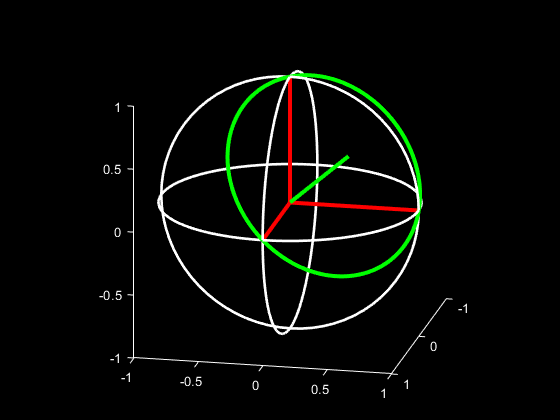

step = pi/36;
theta = (pi/2)*ones(181,1); % (pi/2)*ones(181,1); % (0:step:pi)';
phi = 0:step:2*pi;

Cx = sin(theta)*cos(phi);
Cy = sin(theta)*sin(phi);
Cz = repmat(cos(theta), [1 size(phi,2)]);

C1 = [Cx(:)'; Cy(:)'; Cz(:)'];

C2 = rotate_3D(C1, 'x', pi/2);
C3 = rotate_3D(C1, 'y', -pi/2);

b = sqrt(3)/3*[1 1 1]'; % 1st bissectrice vector
S1 = zeros(3, 121);

for k = 0:121
    S1(:,k+1) = rotate_3D([1 0 0]', 'any', 2*pi*k/363, b);
end

S2 = rotate_3D(S1, 'any', 2*pi/3, b);
S3 = rotate_3D(S1, 'any', -2*pi/3, b);

figure;
set(gcf, 'Color', [0 0 0]);
plot3(C1(1,:), C1(2,:), C1(3,:), 'Color', 'w', 'LineWidth', 2), hold on;
plot3(C2(1,:), C2(2,:), C2(3,:), 'Color', 'w', 'LineWidth', 2), hold on;
plot3(C3(1,:), C3(2,:), C3(3,:), 'Color', 'w', 'LineWidth', 2), hold on;

line([0 1], [0 0], [0 0], 'Color', 'r', 'LineWidth', 3), hold on;
line([0 0], [0 1], [0 0], 'Color', 'r', 'LineWidth', 3), hold on;
line([0 0], [0 0], [0 1], 'Color', 'r', 'LineWidth', 3), hold on;
line([0 sqrt(3)/3], [0 sqrt(3)/3], [0 sqrt(3)/3], 'Color', 'g', 'LineWidth', 3), hold on;

plot3(S1(1,:), S1(2,:), S1(3,:), 'Color', 'g', 'LineWidth', 3), hold on;
plot3(S2(1,:), S2(2,:), S2(3,:), 'Color', 'g', 'LineWidth', 3), hold on;
plot3(S3(1,:), S3(2,:), S3(3,:), 'Color', 'g', 'LineWidth', 3), hold on;

set(gca, 'Color', [0 0 0], 'XColor', [1 1 1], 'YColor', [1 1 1], 'ZColor', [1 1 1]);
axis equal, axis square, axis tight;
view([102,17]);